clc
close all
% confident intervals for SVM
error  =1 - SVM_accuracies_in_test/100;

Unrecognized function or variable 'SVM_accuracies_in_test'.


inter = 1.96 .* sqrt( (error .* (1 - error)) ./ 2000)
low = SVM_accuracies_in_test/100-inter;
up = SVM_accuracies_in_test/100+inter;
plot(SVM_accuracies_in_test/100,'LineWidth',2)
hold on
plot(up,'k')
plot(low,'k')
grid on
legend('Validation accuracy', 'Conidence interval')
xlabel('index',"FontSize",16)
ylabel('Accuracy',"FontSize",16)

hold off

[m,idx] = min(inter)

low(idx)
up(idx)

plot(SVM_accuracies_in_test/100,'LineWidth',2)
hold on 
plot(SVM_accuracies_in_train/100)
grid on
xlabel('index',"FontSize",16)
ylabel('Accuracy',"FontSize",16)
legend('Validation', 'Training')
hold off


## test error for probel 4, SVM RBK kfold

test_error2 = ones(length(models),1);
for ii = 1:length(models)
    mdl = models{ii};
    [predicted_label, accuracy, dec_values_L] = svmpredict(YTest, XTest,mdl);
%     y = 1-predicted_label.*YTest;
%     loss = max([zeros(length(y),1),y]);
%     %     loss = hl(YTest,predicted_label);
%     test_error(i) = sum(loss)/length(YTest)
    test_error2(ii)= accuracy(2);
end

Accuracy = 57.15% (1143/2000) (classification)
Accuracy = 57% (1140/2000) (classification)
Accuracy = 57% (1140/2000) (classification)
Accuracy = 86.25% (1725/2000) (classification)
Accuracy = 97.65% (1953/2000) (classification)
Accuracy = 97.3% (1946/2000) (classification)
Accuracy = 97.3% (1946/2000) (classification)
Accuracy = 97.3% (1946/2000) (classification)
Accuracy = 97.3% (1946/2000) (classification)
Accuracy = 97.3% (1946/2000) (classification)


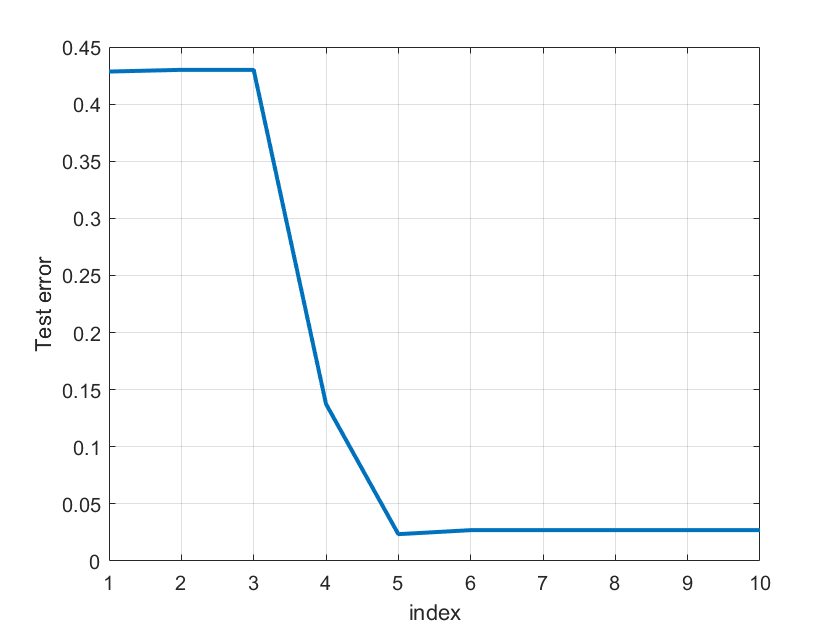

plot(test_error2,"LineWidth",2)
grid on
xlabel("index")
ylabel('Test error')

% confidence interval for LR
error  =1 - LRaccuracies;

inter = 1.96 .* sqrt( (error .* (1 - error)) ./ 2000)
low = LRaccuracies-inter;

up = LRaccuracies+inter;
low(idx)
up(idx)

plot(LRaccuracies,'LineWidth',2)
hold on
plot(up,'k')
plot(low,'k')
grid on
legend('Validation accuracy', 'Conidence interval')
xlabel('index',"FontSize",16)
ylabel('Accuracy',"FontSize",16)

hold off

[m,idx] = min(inter)




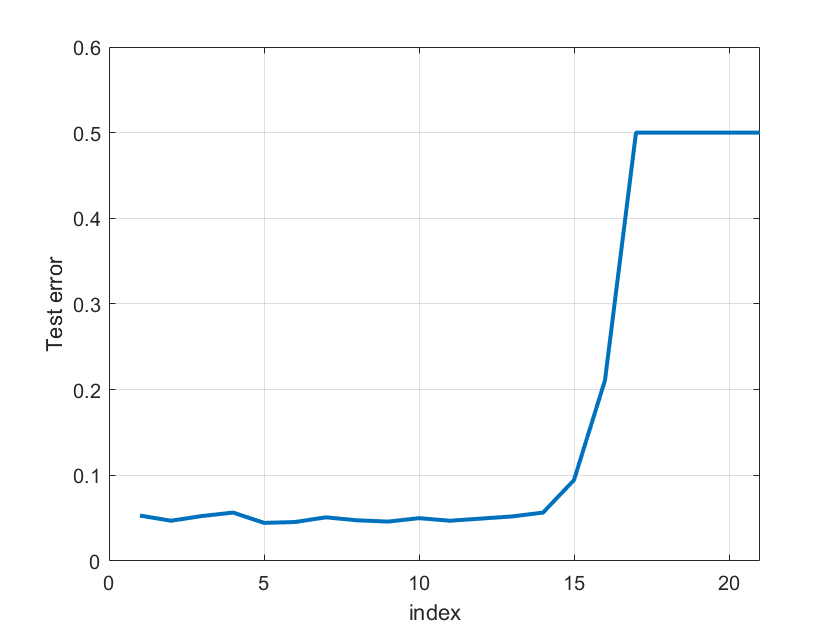

% test error for three, LR
error = Label-YTest;
e2 = error.^2/length(YTest);

plot(sum(e2,1),"LineWidth",2)
grid on
xlabel("index")
ylabel('Test error')
xlim([0,21])


test_error2 = ones(length(SVMmdls),1);
for ii = 1:length(SVMmdls)
    mdl = SVMmdls{ii};
    [predicted_label, accuracy, dec_values_L] = svmpredict(YTest, XTest,mdl);
%     y = 1-predicted_label.*YTest;
%     loss = max([zeros(length(y),1),y]);
%     %     loss = hl(YTest,predicted_label);
%     test_error(i) = sum(loss)/length(YTest)
    test_error2(ii)= accuracy(2);
end

Accuracy = 57% (1140/2000) (classification)
Accuracy = 57% (1140/2000) (classification)
Accuracy = 57% (1140/2000) (classification)
Accuracy = 57% (1140/2000) (classification)
Accuracy = 57% (1140/2000) (classification)
Accuracy = 74.85% (1497/2000) (classification)
Accuracy = 80.65% (1613/2000) (classification)
Accuracy = 88.25% (1765/2000) (classification)
Accuracy = 93.05% (1861/2000) (classification)
Accuracy = 95.95% (1919/2000) (classification)
Accuracy = 97.6% (1952/2000) (classification)
Accuracy = 97.75% (1955/2000) (classification)
Accuracy = 97.55% (1951/2000) (classification)
Accuracy = 97.3% (1946/2000) (classification)


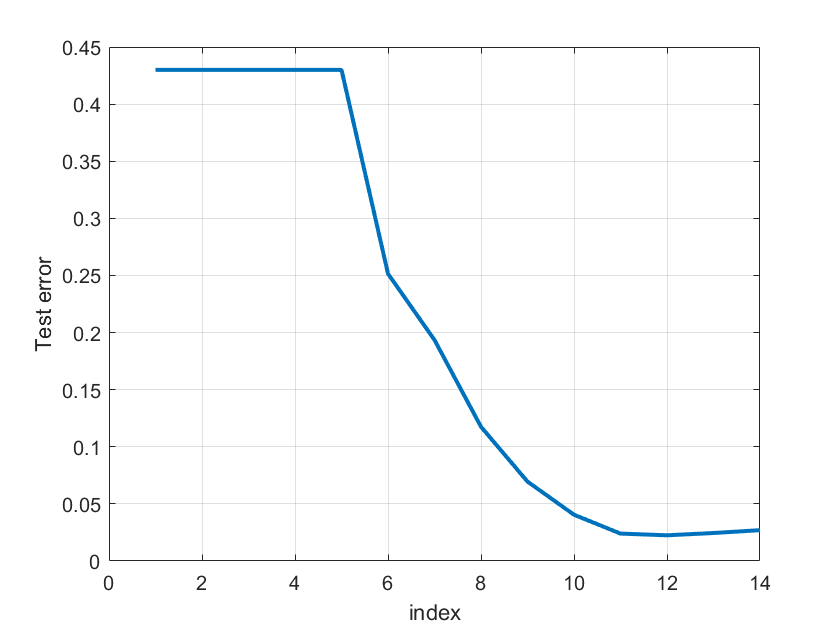

Error using xlim (line 31)
Limits must be a 2-element vector of increasing numeric values.

plot(test_error2,"LineWidth",2)
grid on
xlabel("index")
ylabel('Test error')
xlim([1:ii])